clear;

三维简单单摆系统公式推导

do_Formular = false;
if do_Formular
syms a(t) b(t)
gx = [1;0;0];
gy = [0;1;0];
gz = [0;0;1];
% get_R_y(pi/2)*get_R_y(a)*get_R_z(b)
% get_R_y(a+pi/2)*get_R_z(b)
RB = simplify(get_R_y(a+pi/2)*get_R_z(b));

omegaB = simplify(subs(...
	get_R_z(b)'*gy*diff(a,t)+gz*diff(b,t), ...
	[a';b'],[a;b]));
% simplify(subs(R'*diff(R,t),[a';b'],[a;b])) - ...
% 	skew(omegaB(t))
omegaB_I = simplify(RB*omegaB);
domegaBdt = simplify(...
	subs(RB'*diff(omegaB_I,t),[a';b'],[a;b]));

syms r_x(t) r_y(t) r_z(t)
syms L
r0 = [r_x(t);r_y(t);r_z(t)];
r1 = r0 + L*RB*gx;
dr1dt = simplify(...
	diff(r0,t) + L*RB*skew(omegaB(t))*gx);
ddr1dtdt = simplify(...
	diff(r0,t,2) + L*RB*skew(domegaBdt(t))*gx + ...
	 + L*RB*skew(omegaB(t))*skew(omegaB(t))*gx);
% diff(r1,t)-dr1dt
% diff(r1,t,2)-ddr1dtdt

Tr = [eye(3), [...
	-L*cos(a)*cos(b),	L*sin(a)*sin(b);
	0,					L*cos(b);
	L*sin(a)*cos(b),	L*cos(a)*sin(b)]];
dTrdt = [zeros(3), [...
	L*sin(a)*cos(b)*diff(a,t)+L*cos(a)*sin(b)*diff(b,t),	L*cos(a)*sin(b)*diff(a,t)+L*sin(a)*cos(b)*diff(b,t);
	0,														-L*sin(b)*diff(b,t);
	L*cos(a)*cos(b)*diff(a,t)-L*sin(a)*sin(b)*diff(b,t),	-L*sin(a)*sin(b)*diff(a,t)+L*cos(a)*cos(b)*diff(b,t)]];

% Tr*diff([r0;a;b],t)-dr1dt
% simplify(Tr*diff([r0;a;b],t,2)+dTrdt*diff([r0;a;b],t)-ddr1dtdt)
syms g % g = 9.8
M = simplify(simplify(subs(Tr'*Tr,[a',b',r_x',r_y',r_z',L'],[a,b,r_x,r_y,r_z,L])))
D = simplify(subs(Tr'*dTrdt,[a',b',r_x',r_y',r_z',L'],[a,b,r_x,r_y,r_z,L]));
Fg = simplify(subs(-Tr'*(-gz*g),[a',b',r_x',r_y',r_z',L'],[a,b,r_x,r_y,r_z,L]));
F = simplify(D*diff([r0;a;b],t) + Fg)
end

角度函数测试

do_AngleFunctionTest = false;
if do_AngleFunctionTest
T1 = 3;
T2 = 1;
theta_set = [];
dthetadt_set = [];
ddthetadtdt_set = [];
t_set = linspace(0,2*T1+T2,10000);
for t = t_set
	if t>=0 && t<=1/3*T1
		theta = sin(3*pi/T1*t)-3*pi/T1*t;
		dthetadt = 3*pi/T1*cos(3*pi/T1*t)-3*pi/T1;
		ddthetadtdt = -3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
	elseif t>1/3*T1 && t<=2/3*T1
		theta = 2*sin(3*pi/T1*t)-pi;
		dthetadt = 2*3*pi/T1*cos(3*pi/T1*t);
		ddthetadtdt = -2*3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
	elseif t>2/3*T1 && t<=T1
		theta = sin(3*pi/T1*t)+3*pi/T1*t-3*pi;
		dthetadt = 3*pi/T1*cos(3*pi/T1*t)+3*pi/T1;
		ddthetadtdt = -3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
	elseif t>T1 && t<=T1+T2
		theta = 0;
		dthetadt = 0;
		ddthetadtdt = 0;
	elseif t>T1+T2 && t<=4/3*T1+T2
		theta = -sin(3*pi/T1*(t-T1-T2))+3*pi/T1*(t-T1-T2);
		dthetadt = -3*pi/T1*cos(3*pi/T1*(t-T1-T2))+3*pi/T1;
		ddthetadtdt = 3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
	elseif t>4/3*T1+T2 && t<=5/3*T1+T2
		theta = -2*sin(3*pi/T1*(t-T1-T2))+pi;
		dthetadt = -2*3*pi/T1*cos(3*pi/T1*(t-T1-T2));
		ddthetadtdt = 2*3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
	elseif t>5/3*T1+T2 && t<=2*T1+T2
		theta = -sin(3*pi/T1*(t-T1-T2))-3*pi/T1*(t-T1-T2)+3*pi;
		dthetadt = -3*pi/T1*cos(3*pi/T1*(t-T1-T2))-3*pi/T1;
		ddthetadtdt = 3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
	else
		theta = 0;
		dthetadt = 0;
		ddthetadtdt = 0;
	end
	theta_set = [theta_set;theta];
	dthetadt_set = [dthetadt_set;dthetadt];
	ddthetadtdt_set = [ddthetadtdt_set;ddthetadtdt];
end
plot(t_set,theta_set,'r-', ...
	t_set,dthetadt_set,'b-', ...
	t_set,ddthetadtdt_set,'g-');
legend('\theta','d\theta/dt','d^2\theta/{dt}^2');
grid on; grid MINOR;
end

连接点运动特性反算

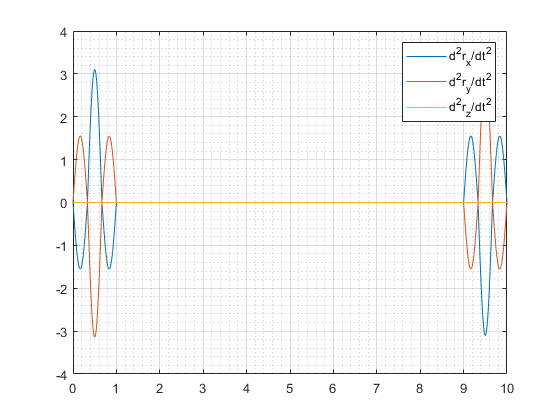

t_total = 10;
T1_alpha = 1;
T2_alpha = t_total - 2*T1_alpha;
T1_beta = T1_alpha;
T2_beta = t_total - 2*T1_beta;
L = 1;
t_set = linspace(0,t_total,1e5);
ddrdtdt_set = zeros(3,numel(t_set));
g = 0;
for t_Nr = 1:numel(t_set)
	t = t_set(t_Nr);
	ddrdtdt = get_Acceleration_Point0_2(...
		t,T1_alpha,T2_alpha,T1_beta,T2_beta,L,g);
	ddrdtdt_set(:,t_Nr) = ddrdtdt;

end
drdt_set = cumtrapz(t_set,ddrdtdt_set')';
r_set = cumtrapz(t_set,drdt_set')';

plot(t_set,ddrdtdt_set);
legend('d^2r_x/{dt}^2','d^2r_y/{dt}^2','d^2r_z/{dt}^2');
grid on; grid MINOR;

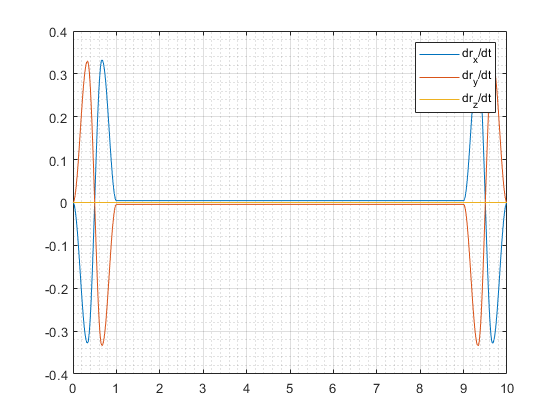

plot(t_set,drdt_set);
legend('dr_x/dt','dr_y/dt','dr_z/dt');
grid on; grid MINOR;

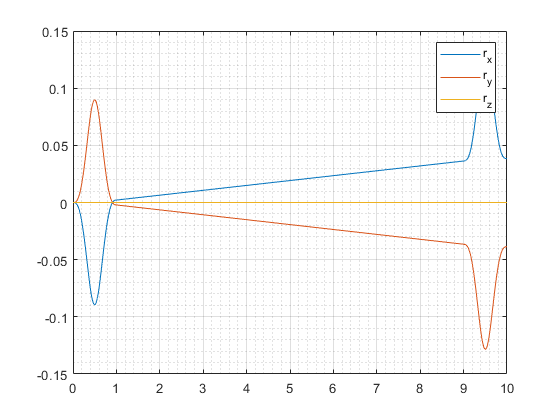

plot(t_set,r_set);
legend('r_x','r_y','r_z');
grid on; grid MINOR;

r_set(:,end)

ans =     0.0384
   -0.0386
         0


function [theta,dthetadt,ddthetadtdt] = AngleFunction(t,T1,T2,lambda)
if nargin < 4
	lambda = 1;
end

if t>=0 && t<=1/3*T1
	theta = sin(3*pi/T1*t)-3*pi/T1*t;
	dthetadt = 3*pi/T1*cos(3*pi/T1*t)-3*pi/T1;
	ddthetadtdt = -3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
elseif t>1/3*T1 && t<=2/3*T1
	theta = 2*sin(3*pi/T1*t)-pi;
	dthetadt = 2*3*pi/T1*cos(3*pi/T1*t);
	ddthetadtdt = -2*3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
elseif t>2/3*T1 && t<=T1
	theta = sin(3*pi/T1*t)+3*pi/T1*t-3*pi;
	dthetadt = 3*pi/T1*cos(3*pi/T1*t)+3*pi/T1;
	ddthetadtdt = -3*pi/T1*3*pi/T1*sin(3*pi/T1*t);
elseif t>T1 && t<=T1+T2
	theta = 0;
	dthetadt = 0;
	ddthetadtdt = 0;
elseif t>T1+T2 && t<=4/3*T1+T2
	theta = -sin(3*pi/T1*(t-T1-T2))+3*pi/T1*(t-T1-T2);
	dthetadt = -3*pi/T1*cos(3*pi/T1*(t-T1-T2))+3*pi/T1;
	ddthetadtdt = 3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
elseif t>4/3*T1+T2 && t<=5/3*T1+T2
	theta = -2*sin(3*pi/T1*(t-T1-T2))+pi;
	dthetadt = -2*3*pi/T1*cos(3*pi/T1*(t-T1-T2));
	ddthetadtdt = 2*3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
elseif t>5/3*T1+T2 && t<=2*T1+T2
	theta = -sin(3*pi/T1*(t-T1-T2))-3*pi/T1*(t-T1-T2)+3*pi;
	dthetadt = -3*pi/T1*cos(3*pi/T1*(t-T1-T2))-3*pi/T1;
	ddthetadtdt = 3*pi/T1*3*pi/T1*sin(3*pi/T1*(t-T1-T2));
else
	theta = 0;
	dthetadt = 0;
	ddthetadtdt = 0;
end

lambda = lambda/180*pi/5;
theta = lambda*theta;
dthetadt = lambda*dthetadt;
ddthetadtdt = lambda*ddthetadtdt;
end

function ddrdtdt = get_Acceleration_Point0(...
	t,T1_alpha,T2_alpha,T1_beta,T2_beta,L,g)

[alpha,dalphadt,ddalphadtdt] = AngleFunction(t,T1_alpha,T2_alpha);
[beta,dbetadt,ddbetadtdt] = AngleFunction(t,T1_beta,T2_beta);

ddrxdtdt = L*cos(alpha)*cos(beta)*ddalphadtdt - ...
	L*sin(alpha)*sin(beta)*ddbetadtdt - ...
	L*sin(alpha)*cos(beta)*(dalphadt^2+dbetadt^2) - ...
	2*L*cos(alpha)*sin(beta)*dalphadt*dbetadt;
ddrydtdt = -L*cos(beta)*ddbetadtdt + ...
	L*sin(beta)*dbetadt^2;
ddrzdtdt = -L*sin(alpha)*cos(beta)*ddalphadtdt - ...
	L*cos(alpha)*sin(beta)*ddbetadtdt - ...
	g - ...
	L*cos(alpha)*cos(beta)*(dalphadt^2+dbetadt^2) + ...
	2*L*sin(alpha)*sin(beta)*dalphadt*dbetadt;

ddrdtdt = [ddrxdtdt;ddrydtdt;ddrzdtdt];
end

function ddrdtdt = get_Acceleration_Point0_2(...
	t,T1_alpha,T2_alpha,T1_beta,T2_beta,L,g,ddrzdtdt)
if nargin < 8
	t_total = 2*T1_alpha+T2_alpha;
	ddrzdtdt = 0*sin(2*pi*t/t_total);
end
[alpha,dalphadt,ddalphadtdt] = AngleFunction(t,T1_alpha,T2_alpha,5);
[beta,dbetadt,ddbetadtdt] = AngleFunction(t,T1_beta,T2_beta,5);

M = [-cos(alpha)*cos(beta),		0;
	sin(alpha)*sin(beta),		cos(beta)];
F = [...
	sin(alpha)*cos(beta)*ddrzdtdt+L*(cos(beta))^2*ddalphadtdt+g*sin(alpha)*cos(beta)-L*sin(2*beta)*dalphadt*dbetadt;
	cos(alpha)*sin(beta)*ddrzdtdt+L*ddbetadtdt+g*cos(alpha)*sin(beta)+L/2*sin(2*beta)*dalphadt*dalphadt];
ddrdtdt = -M\F;
ddrdtdt = [ddrdtdt;ddrzdtdt];
end